# カメラ特性評価

## 開始列開始点,開始列最終点

## 最終列開始点,最終列最終点    を選択

clear;close;

mousemode=false;%座標選択したい場合true

v=VideoReader("1ms64.mp4");
img=read(v,1);
if mousemode
    imshow(img);
    r=drawpoint('HandleVisibility',"on");
    p1=r.Position;%開始列の始まり
    r=drawpoint('HandleVisibility',"on");
    p8=r.Position;%開始列の終わり
    r=drawpoint('HandleVisibility',"on");
    p57=r.Position;%最終列の始まり
    r=drawpoint('HandleVisibility',"on");
    p64=r.Position;%最終列の終わり
else
    p1=[ 1.22075e+03,2.0225e+02];
    p8=[ 1.04825e+03,1.9625e+02];
    p57=[1.22675e+03,3.7475e+02];
    p64=[1.05125e+03,3.7025e+02];
end

## 座標線形補完

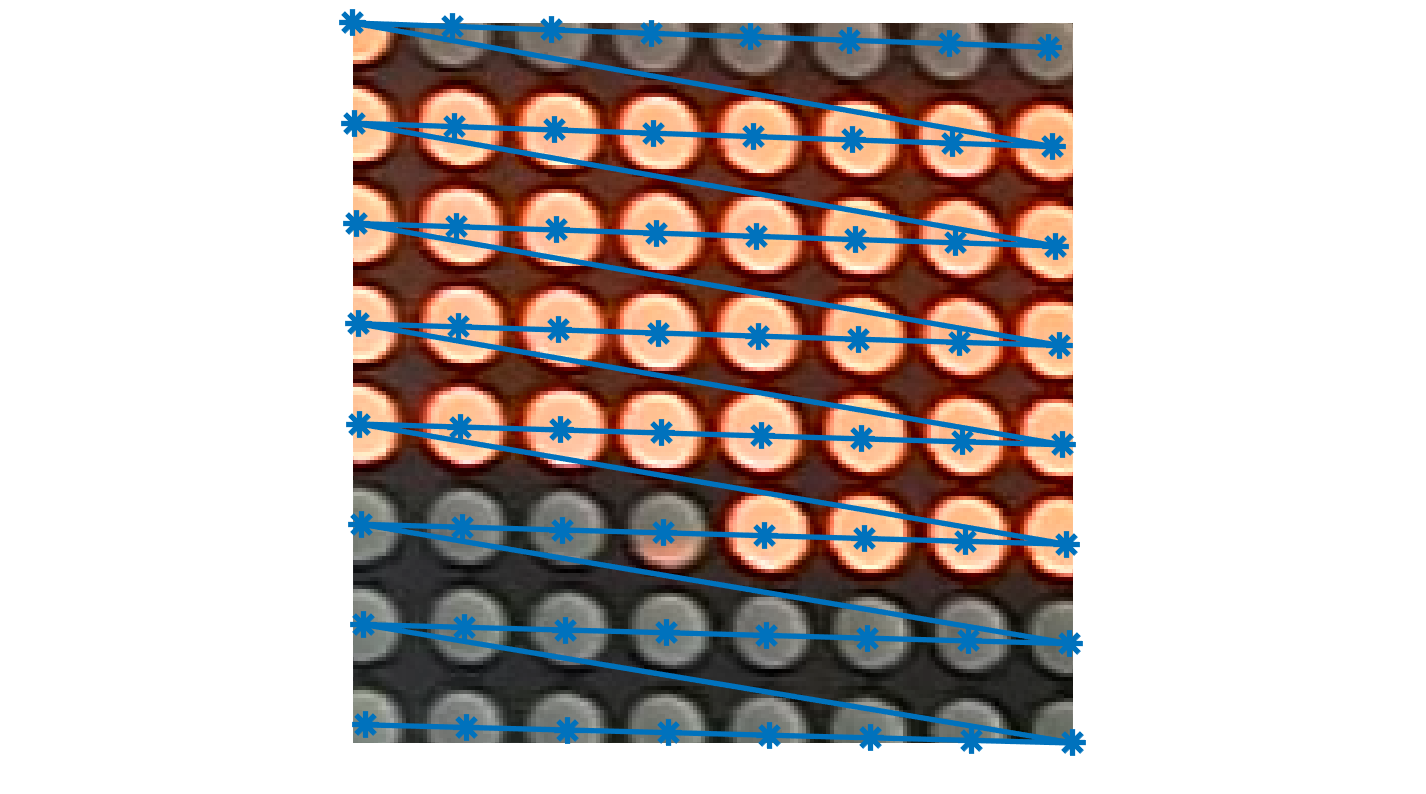

p=zeros(8,8,2);
for i=1:8
    for j=1:8
        A=p1+(p8-p1)/7*(i-1);
        B=p57+(p64-p57)/7*(i-1);
        C=A+(B-A)/7*(j-1);
        p(i,j,:)=C;
    end
end
x=reshape(p(:,:,1),[64,1]);
y=reshape(p(:,:,2),[64,1]);

close
imshow(img)
hold on
plot(x,y,'*-','LineWidth',4,'MarkerSize',20)
xlim([min(x),max(x)])
ylim([min(y),max(y)])
hold off

## 時間取得

num=1:64;
count=0;st_pre=0;
allframe=1:v.NumFrames;
stall=zeros(size(allframe));
shutterspeed=zeros(size(allframe));
for i=allframe
    img=read(v,i);
    c=impixel(img,x,y);
    r=c(:,1);
    th=(max(r)+min(r))/2;
    bin=r>th;
    if(bin(64)&&bin(1)) %64bit目と1bit目が連続
        st=max(num(not(bin)));
        et=min(num(not(bin)))+64;
    else %通常
        st=min(num(bin));
        et=max(num(bin));
    end
    
    shat_t=et-st;
    
    if st_pre>st%前回の時刻より早い（LEDが一周した）
        count=count+1;
    end
    st_pre=st;%前回のカメラ時刻更新
    
    st_save=st+count*64;%ledのループ回数分時間追加
    et_save=et+count*64;
    stall(i)=st_save;
    shutterspeed(i)=shat_t;
    
end
stall=stall/1000;%ms to sec

## ledの切り替え周期を反映

led_dt=1;%ms
stall=stall*led_dt;
shutterspeed=shutterspeed*led_dt;

## plot

close;
plot(stall);
hold on;

fps=allframe(end)/stall(end)

fps = 30.1215

fps=v.FrameRate

fps = 30.0146

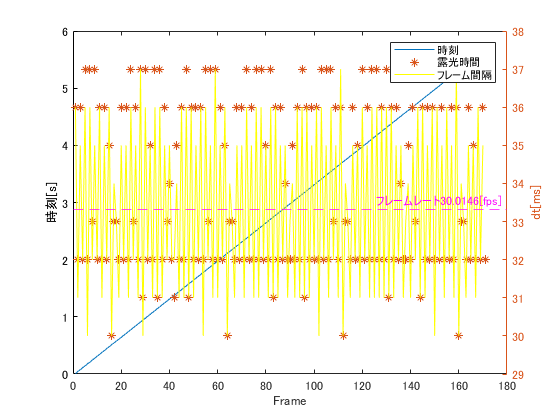

frame_dt=1000*diff(stall);

xlabel Frame;
ylabel 時刻[s];

yyaxis right;
plot(shutterspeed,'*');
plot(frame_dt,'-y');
yline(1000/fps,'--m', ...
    "フレームレート"+num2str(v.FrameRate)+"[fps]")
hold off;
ylabel dt[ms];
legend 時刻 露光時間 フレーム間隔;

% xlim([0,100])

## 統計

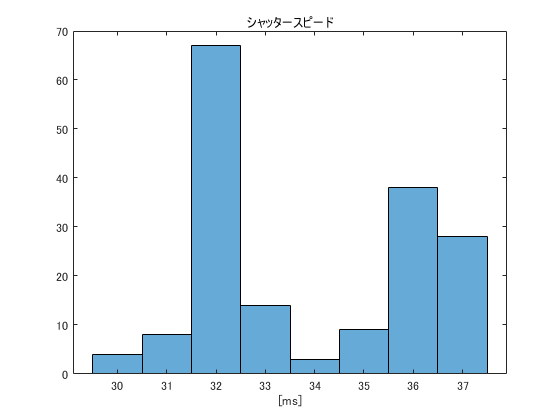

close;
histogram(shutterspeed);title シャッタースピード;xlabel [ms]

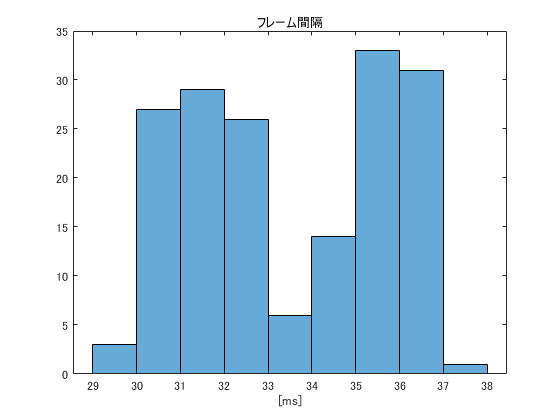

histogram(frame_dt);title フレーム間隔;xlabel [ms]